# **R-factor: Compare surface subsidence computed numerically with Geertsmaa's solutions and with Dyskin's solutions**

## Introduction

**Dyskin's solutions**

see formulas 20, 21, 32 and 33 in Dyskin, A., Pasternak, E., and Shapiro, S. A. (2020).  

Subsidence, uplift and shift due to fluid extraction and production in a 

finite reservoir. International Journal for Numerical and Analytical Methods in

Geomechanics (in review)

**Geertsmaa's solutions**

see formulas 6, 7 in Geertsma, J. (1973). Land subsidence above compacting oil 

and gas reservoirs. Journal of Petroleum Technology, 25(06), 734-744.

**Authors**: Ivan Abakumov

**Publication date**: 25th of February 2020

**E-mail**: ivan.abakumov@fu-berlin.de

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Load G-file and comsol data

% Model 5 - constant overburden model 
% Model 6 - Groningen model 
% Model 7 - Groningen model, but different permeability of basement
Results = MLD('/home/ivan/Desktop/Comsol/My_model_5_results.mat');
G = MLD('/home/ivan/Desktop/Comsol/My_model_5_G_file.mat');

## Plot pressure vs displacement

We consider land surface subsidence due to compaction of the disc-shaped reservoir of radius R and thickness H with the upper boundary at depth D embedded in an elastic half-space. 

- Introduce the main parameters:

D = 3000; % m - depth of the upper boundary 
R = 3000; % m - radius of the reservoir
H = 300;  % m - thickness of the reservoir
dP = 16.52*1e6; % Pa - pore pressure change


nu = 0.2; % Poisson's ratio of the surrounding medium

ov.K  = 12.0*1e9; % bulk modulus (dr) of the overburden
ov.G  =  9.0*1e9; % shear modulus (dr) of the overburden
ov.alpha = 0.3;   % Biot coefficient (overburden)
res.K = 13.3*1e9; % bulk modulus (dr) of the reservoir
res.G = 10.0*1e9; % shear modulus (dr) of the reservoir
res.alpha = 0.95;   % Biot coefficient (reservoir)

    2. Define uniaxisal compaction coefficient


$$c_m = 1/3 (\frac{1+\nu}{1-\nu}) \frac{\alpha
}{K}
$$



$$c_m = 1/2 (\frac{1 - 2\nu}{1-\nu}) \frac{\alpha}{G}$$



$$c_m = \frac{\alpha}{K+4/3G}$$


$\alpha = 1 - K_{dr}/K_{gr}$- the poroelastic Bio coefficient, 

$K_{dr}$ - bulk modulus of rock matrix (drained skeleton)

$K_{gr}$ - bulk modulus of the grain meterial

$\nu = \frac{3K - 2G}{2(3K+G)}$ - Poisson's ratio

res.nu = (3*res.K - 2*res.G)/(3*res.K + res.G)/2

res = struct with fields:
        K: 1.3300e+10
        G: 1.0000e+10
    alpha: 0.9500
       nu: 0.1994



cm = (1+res.nu)/(1-res.nu)*res.alpha/res.K/3;
disp(['Cm, definition 1: cm = ' num2str(cm)])

Cm, definition 1: cm = 3.567e-11



cm = (1-2*res.nu)/(1-res.nu)*res.alpha/res.G/2;
disp(['Cm, definition 2: cm = ' num2str(cm)])

Cm, definition 2: cm = 3.567e-11



cm = res.alpha/(res.K+4/3*res.G);
disp(['Cm, definition 3: cm = ' num2str(cm)])

Cm, definition 3: cm = 3.567e-11



res.cm = cm; 

    3. Define reservoir compaction: 


$$b = c_m \cdot \delta P \cdot H$$
  

b_cal = res.cm*dP*H; 

disp(['Estimated reservoir compaction = ' num2str(b_cal)])

Estimated reservoir compaction = 0.17678



b_mod = 0.159;
disp(['Modeled reservoir compaction = ' num2str(b_mod)])

Modeled reservoir compaction = 0.159


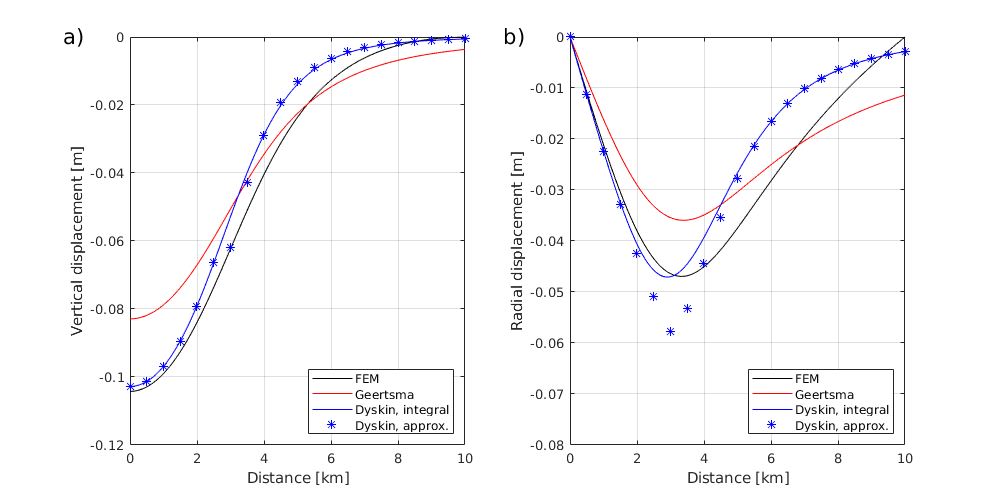

% FEM subsidence
Uz.model5 = Results.disp_y(:,1,101)'-Results.disp_y(:,1,1)'; 
Ur.model5 = Results.disp_x(:,1,101)'-Results.disp_x(:,1,1)'; 

% Geertsma
uz = get_subsidence_vertical_Geertsma(D,R,G.xx); 
Uz.geertsma = -2*b_cal*(1-res.nu)*uz; 

ur = get_subsidence_radial_Geertsma(D,R,G.xx); 
Ur.geertsma = +2*b_cal*(1-res.nu)*ur; 

% Dyskin, integral solution
uz = get_subsidence_vertical_Dyskin_integral(D,R,G.xx); 
Uz.dyskin_int = b_mod*uz;

ur = get_subsidence_radial_Dyskin_integral(D,R,G.xx); 
Ur.dyskin_int = -b_mod*(3-2*res.nu)/(1-res.nu)/2*ur;

% Dyskin, approximate expressions
r = 0:500:10000; 
uz = get_subsidence_vertical_Dyskin(D,R,r); 
Uz.dyskin_app = b_mod*uz;

ur = get_subsidence_radial_Dyskin(D,R,r); 
Ur.dyskin_app = b_mod*(3-2*res.nu)/(1-res.nu)*ur;

% Plot results

figure(433)
fig = figure('Position', [1 1 1000 500]);
subplot(1,2,1)
plot(G.xx/1e3, Uz.model5+0.0073, 'k')
hold on
plot(G.xx/1e3,  Uz.geertsma, 'r')
plot(G.xx/1e3, -Uz.dyskin_int, 'b')
plot(r/1e3,    -Uz.dyskin_app, 'b*')
legend('FEM', 'Geertsma', 'Dyskin, integral', 'Dyskin, approx.', 'Location', 'southeast')
xlabel('Distance [km]')
ylabel('Vertical displacement [m]')
grid on
text(-2, 0, 'a)', 'FontSize', 16) 
axis([0 10 -0.12 0])

subplot(1,2,2)
plot(G.xx/1e3, Ur.model5, 'k')
hold on
plot(G.xx/1e3, -Ur.geertsma, 'r')
plot(G.xx/1e3, Ur.dyskin_int, 'b')
plot(r/1e3,    Ur.dyskin_app, 'b*')
legend('FEM', 'Geertsma', 'Dyskin, integral', 'Dyskin, approx.', 'Location', 'southeast')
xlabel('Distance [km]')
ylabel('Radial displacement [m]')
grid on
text(-2, 0, 'b)', 'FontSize', 16) 
axis([0 10 -0.08 0])